# Estimation Theory : Assignment 3

### Part a)

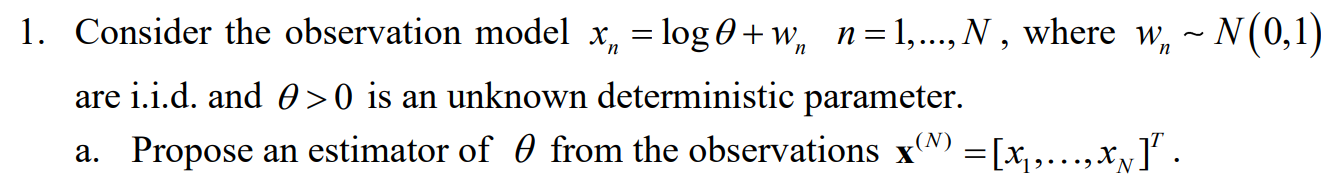

#### We simulate the statistical model of the data samples

- We choose the value of theta randomly to see that the estimator works for all values of theta but it is deterministic for the rest of the simulation.

- We add iid samples of random GWN.

clear ; clc ; clf ;

w_ = @(N) randn(1,N) 

w_ = function_handle with value:
    @(N)randn(1,N)



M = 8 ;

theta = ceil(rand()*M)

theta = 4


x_ = @(theta,N) log(theta) + w_(N)

x_ = function_handle with value:
    @(theta,N)log(theta)+w_(N)


#### We derive the ML estimator

We will build the estimator as we derived in the assignment as the sample mean:


$$\hat{\theta \;} \left(\underline{\;x} \right)=\exp \left\lbrack \frac{1}{N}\;\sum_{i=1}^N x_i \right\rbrack =e^{\bar{x} } \;$$


hat_theta_ = @(X) exp(mean(X));

#### We visuallize the results

We plot the distribution of result and see that we indeed got a mean of a normal distribtution as expected.

We compare between the actual and estimated values of theta and also see as expected that both are strictly positive!

N = 1000;
X = x_(theta,N)

X =     2.2132   -0.4128    0.7831    0.1049    1.0669    2.2594    2.3327    2.2355    3.0888    2.3879   -0.5209    2.2385    1.2528    0.3721    2.2332    0.9291    1.9322    1.0982    1.8057    1.0022    2.7967    1.9677    2.0433    1.2733   -1.0378    0.1225    0.7338    1.3740    1.9600    1.5392    1.9260    1.5818    3.2504    0.1061    0.7847   -0.3942    3.9050    2.7654   -0.2121    2.2473    1.5076    0.5485    2.2909    1.7056    0.4380    1.0919    0.1176    0.1638   -0.2596    0.9050


hat_theta = hat_theta_(X)

hat_theta = 3.9945

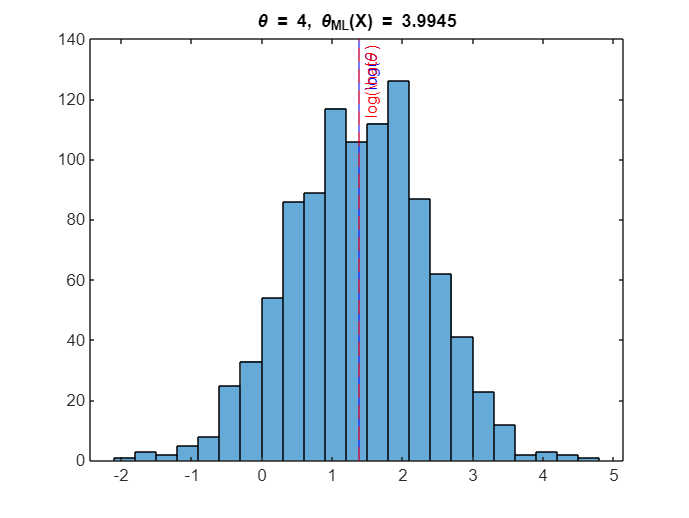

figure ;
histogram(X)
title("\theta = " + num2str(theta) + ", \theta_{ML}(X) = " + num2str(hat_theta))
xline(log(theta),"-b","log(\theta)")
xline(log(hat_theta),"--r","log(\hat{\theta})")

### Part b)

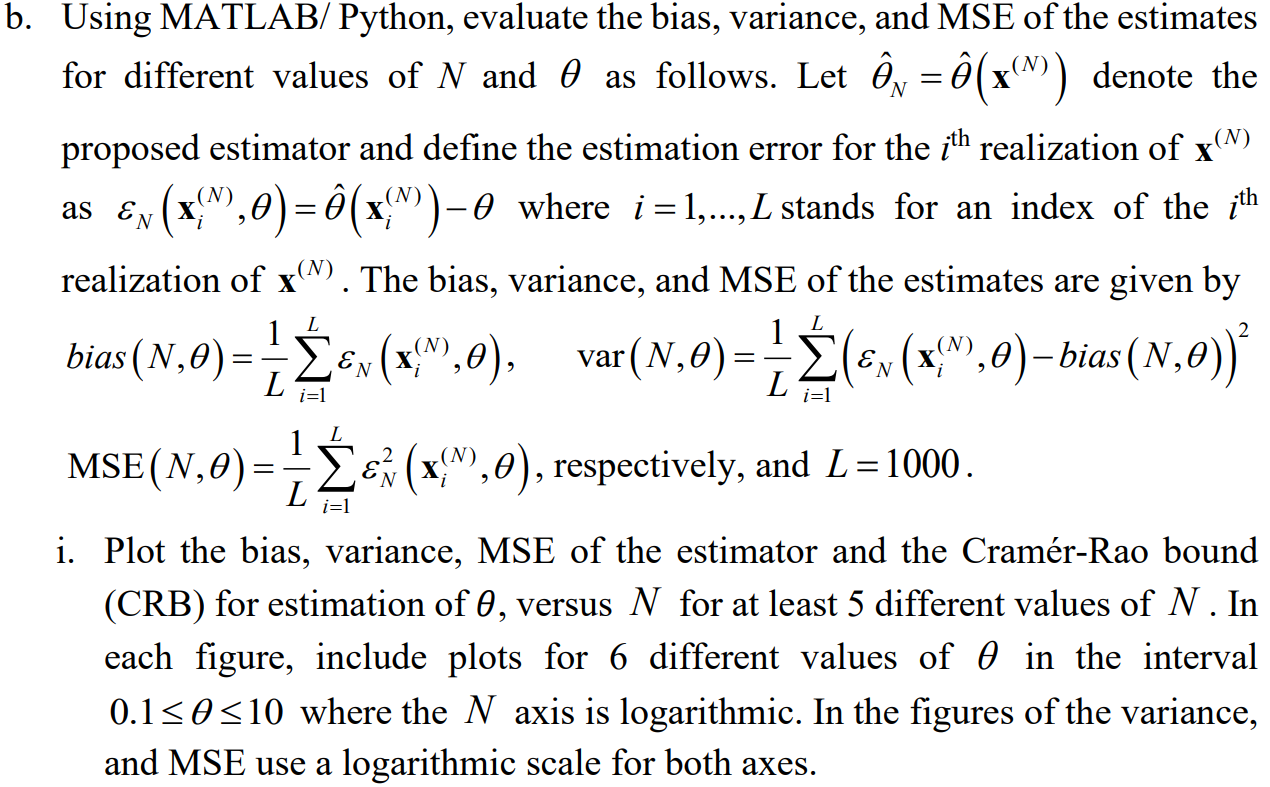

### We will create a function for simulating the evolution of the **bias**,**variance**,**MSE **and the **CRB.**

#### **Estimation Error : **$\varepsilon_N \left(X_i ,\theta \;\right)=\hat{\theta \;} \left(X_i \right)-\theta \;\;$

#### **Bias : **$\textrm{bias}\left(N,\theta \;\right)=\frac{1}{L}\sum_{i=1}^N \varepsilon_N \left(X_i ,\theta \;\right)\;$

function output = Bias(X,hat_theta,theta)
    N = length(X);
    output = zeros(1,N);
    for L = 1:N
        output(L) = mean(hat_theta(X(1:L))-theta);
    end
end

bias = @(X,hat_theta,theta) mean(hat_theta(X)-theta);

#### Variance :$\;\textrm{Var}\left(N,\theta \;\right)=\frac{1}{L}{\sum_{i=1}^N \left({\;\varepsilon }_N \left(X_i ,\theta \;\right)-\textrm{bias}\left(N,\theta \;\right)\;\right)}^2 \;$ 

function output = Variance(X,hat_theta,theta)
    N = length(X);
    output = zeros(1,N);
    B = Bias(X,hat_theta,theta);

    for L=1:N
        
        X_L = X(1:L);
        B_L = B(1:L);
        output(L) = mean( (X_L - B_L).^2 );
    end
end

variance = @(X,hat_theta,theta) mean((hat_theta(X)-theta).^2);

#### MSE :$\;\textrm{MSE}\left(N,\theta \;\right)=\frac{1}{L}{\sum_{i=1}^N {\;\varepsilon }_N \left(X_i ,\theta \;\right)}^2 \;$ 

function output = MSE(X,hat_theta,theta)
    
    N = length(X);
    output = zeros(1,N);


Theta =     0.1000    2.0800    4.0600    6.0400    8.0200   10.0000


    for L=1:N
        X_L = hat_theta(X(1:L));
        output(L) = mean( (X_L - theta).^2 );

N_axis =          100         252         631        1585        3982       10000


    end
end

mse = @(X,hat_theta,theta) mean(hat_theta(X).^2);

#### Plotting the results :

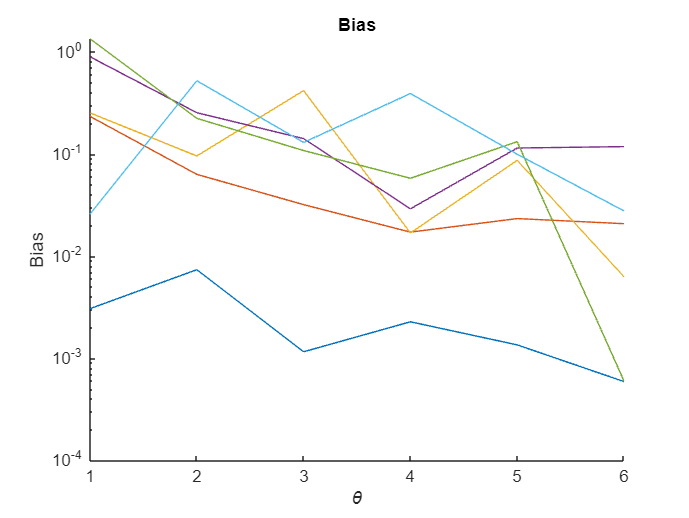

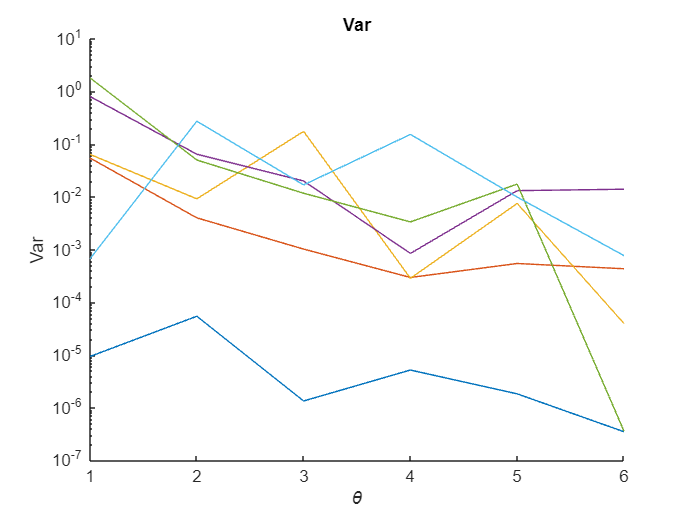

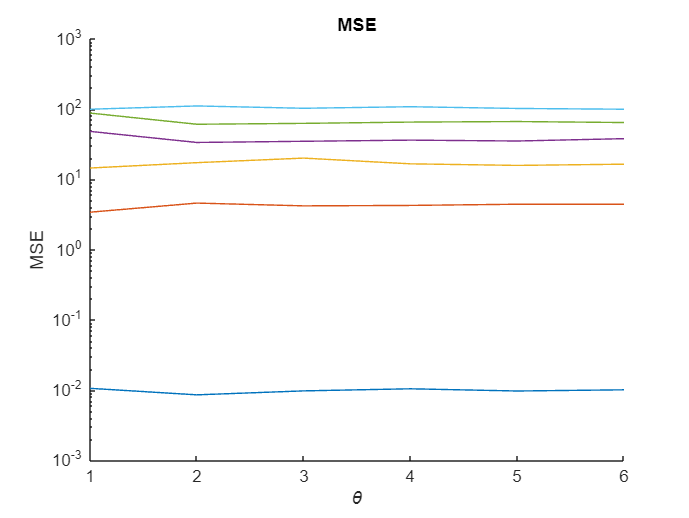

M = 6 ;
Theta = linspace(0.1,10,M)

N = 6 ;
N_axis = ceil(logspace(2,4,N))

Results = zeros(N,M,3);

for i = 1:N
    n = N_axis(i);
    for j = 1:M
        theta = Theta(j);

        % returns the signal of size n for values of theta,n
        X = x_(theta,n);

        % returns Bias,Var,MSE for x and estimator
        Bias_hat_theta = bias(X,hat_theta_,theta);
        Var_hat_theta = variance(X,hat_theta_,theta);
        MSE_hat_theta = mse(X,hat_theta_,theta);



        % places results in tensor F(theta_j,N_i)
        Results(j,i,1) = Bias_hat_theta;
        Results(j,i,2) = Var_hat_theta;
        Results(j,i,3) = MSE_hat_theta;

    end 
end

#### Plot Bias,Var,MSE as a function of $N$:

titles = [ "Bias" , "Var" , "MSE" ] ;

for k = 1 : 3 
    figure;
    hold on;
    for j = 1 : M
        n = N_axis(i);
    
        Data_for_N = Results(j,:,k);
        
        plot(abs(Data_for_N))
        title(titles(k))
        xlabel("\theta")
        ylabel(titles(k))
        

        yscale log ;

    end 

    hold off;
end 














